# PID Compensators

## Introduction

PID compensators are very widely used in industry, particularly for process control applications. Given a system with feedback signal *e*(*t*), the PID compensated control signal is

               $u(t)=K_{\mathrm{prop}}\left(e(t)+\frac{1}{T_I}\,\int_{0}^{t}e(\tau)d\tau+T_D\,\frac{de(t)}{dt}\right)$           (1)                                                                                   

where 

$K_\mathrm{prop}$   proportional gain

$T_I$       integral time (s)

$1/T_I$   reset rate (repeat/s)                       

$T_D$       derivative time (s)

 The Laplace transform of the PID equation is:

               $U(s)=K_{\mathrm{prop}}\left(E(s)+\frac{1}{T_I s}\,E(s)+sT_D\,E(s)\right)$              (2)                                                                                

so that

               $D_{\mathrm{PID}}(s)=\frac{U(s)}{E(s)}=K_{\mathrm{prop}}\left(1+\frac{1}{T_I s}+sT_D\right)$                   (3)

Commercial compensators are provided with setting controls for each of the three parameters $K_{\mathrm{prop}$, $T_I$and $T_D$. They can also be used with and without the integral and derivative terms. The common configurations for the PID compensator are:

## Proportional only

                $D_{\mathrm{P}}(s)=K_{\mathrm{prop}}$                                                            (4)

This type of compensation can be used when dynamic compensation is not needed to achieve the required steday-state acuracy and transient performance. In general, larger values of poportional gain reduce steady-state errors and rise times but tend to increase the size and number of overshoots and setting time.

## Proportional plus Derivative (P+D)

                 $D_{\mathrm{P+D}}(s)=K_{\mathrm{prop}}\left(1+sT_D\right)
=K_{\mathrm{prop}}T_D\,\left(s+1/T_D\right)$       (5)

This configuration adds a zero to the proportional only compensator. This zero is used to increase the system damping thereby improving stability and reducing settling time. The cascade zero may cause a small reduction in rise time and an increase in the size of the first overshoot. Note that derivative action is *never *used alone!

## Proportional plus Integral (P+I)

Integral action may be used alone and its effect is to increase the system type number by 1. That is it makes a type 0 system type 1 and eliminates steady-state step errors[[1]](#_ftn1). However, it is more common to the integral action added with proportional gain in the proportional plus integral confuguration:

                    $D_{\mathrm{P+I}}(s)=K_{\mathrm{prop}}\left(1+\frac{1}{T_I s}\right)=K_{\mathrm{prop}}\left(\frac{s+1/T_I}{s}\right)$       (6)                          

This raises the system type number by 1 and also adds a zero which can offset the destabilising effect of the additional pole. A typical use of this zero would be to cancel the lowest-frequency system pole to allow a faster closed-loop response.

## Full Proportional-Integral-Derivative (PID)

                      $D_{\mathrm{PID}}(s)=K_{\mathrm{prop}}\left(\frac{T_D\,s^2+s+1/T_I}{s}\right)$                      (7)

The PID compensator raises the system type number by 1. It also introduces two zeros which can be used to improve the transient response. Root locus methods can be used to locate these zeros in order to satisfy the steady-state and transient response requirements of a design. There is also an [analytical technique](analpid.doc) for achieving a specified steady-state error performance and defined dominant poles. In industrial practice, however, it is quite common to tune a PID compensator "in the loop" and this is discussed in a companion document ([Tuning a PID Compensator](pid.doc)). The tuning rules are essentially summarised as:

- Choose $K_{\mathrm{prop}}$ to achieve the required speed of response.

- Choose the reset rate $1/T_I$ to achieve desired steady-state performance (may need to re-tune $K_{\mathrm{prop}}$)

- Add derivative action to reduce overshoots and improve settling time.

The effect of the parameters may be summarised as

- Increasing reset rate and proportional gain increases the speed of response and reduces the steady-state error.

- Increasing reset rate reduces stability.

- Increasing derivative time increases stability.

# Zeigler-Nichols Tuning Algorithms

Based on empirical observations of PID tuning strategies for process control, Zeigler and Nichols have proposed two methods of choosing the first-pass settings for PID compensators. The methods only need measured system responses and are generally applicable to type 0 systems of any order that are commonly found in process control applications (i.e. control of level, temperature, pressure, flow, etc.). 

## Step Response Method

Zeigler-Nichols' step response method will work on any system that has an open-loop step response that is an essentially critically or overdamped damped character like that shown in Figure 1.

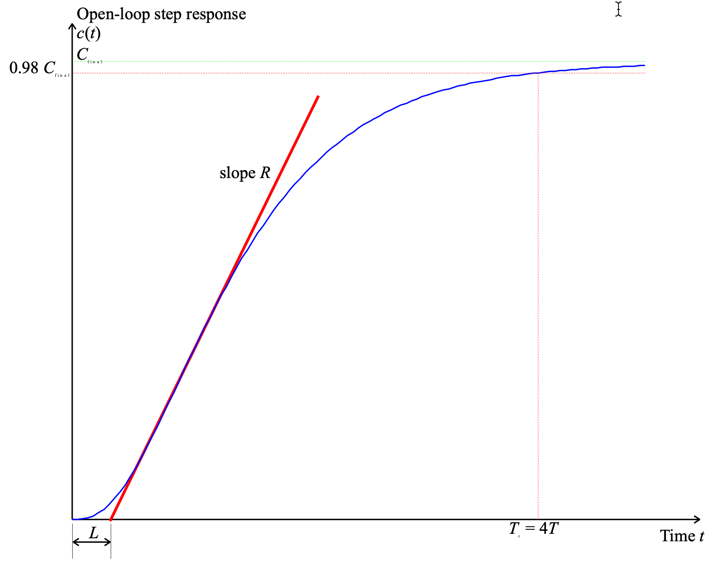

*Figure **1**: Open-loop step response for a typical process control system*

From this response it is necessary to determine only two parameters. 

- The slope *R* of the tangent to the steepest part of the rising edge. 

- The "apparent dead-time" *L* (which is the intersection of the tangent with the time axis).

Given that $a=RL$, the PID parameters are then tuned according to Table 1. 

*Table **1** Tuning parameters for Zeigler-Nichols' time response method*

  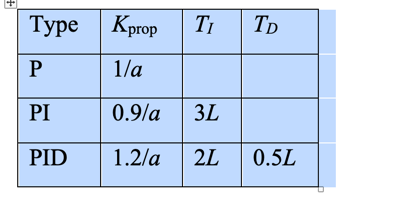

Provided that the open-loop response is stable, it is possible to measure the apparent time constant *T*. For a second order system it can be shown that the settling time (to 98% of the final value) of an overdamped system is approximately 4T. We thus take this as an approximation for any higher-order system that has the general shape indicated in Figure 1. Thus

 $\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;T\approx \frac{T_s }{4}$.                                      .

Given the apparent time constant, Zeigler-Nichols' step response tuning method works reasonably well for

                $0.15\le \frac{L}{T}\le 0.6.$                                  .

Under these conditions, the choice of tuning parameters indicated in Table 1 would give a closed-loop system with good load-disturbance rejection properties. Zeigler-Nichols tuning methods, however, tend to produce systems whose transient response is rather oscillatory and so will need to be tuned further prior to putting the system into closed-loop operation.

## Ultimate sensitivity method

This tuning algorithm works for type 0 systems that have order > 2. It can also be adapted to work in auto-tuning implementations of PID compensators[[2]](#_ftn2). The tuning method relies on being able to find the gain at which the Nyquist response crosses the critical point or equivalently when the root locus crosses the imaginary axis. It can be found experimentally, but requires that the gain be increased in closed-loop operation until the response becomes a sustained oscillation. This may be a dangerous mode of operation in some process control applications! The gain at which the system becomes marginally stable is called $K_u$. The period of oscillation of this frequency is $T_u$. Once these two parameters are known, the PID parameters are selected according to Table 2. 

*Table **2** Tuning parameters for Zeigler-Nichols' ultimate sensitivity method*

 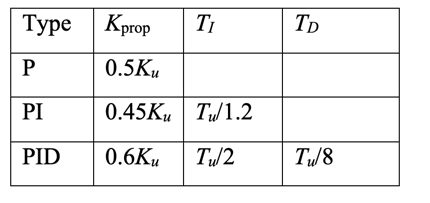

The static gain for the open-loop system is

          
$$K_p=\left.G(s)H(s)\right|_{s=0}$$
            

The ultimate sensitivity tuning method works well if:

           
$$2<K_p\,K_u<20$$
 

but again, the closed-loop response tends to be somewhat under-damped.

# Examples

To illustrate the application of the Zeigler-Nichols tuning rules we take the plant:

          $G(s)=\frac{6}{(s+1)(s+2)(s+3)}$                          .                                 (8)

G = zpk([],[-1;-2;-3],6)


G =
 
          6
  -----------------
  (s+1) (s+2) (s+3)
 
Continuous-time zero/pole/gain model.



The feedback:

H=1; 

Loop transfer function:

GH=G*H;

## Time response method

The open-loop step response of the system is

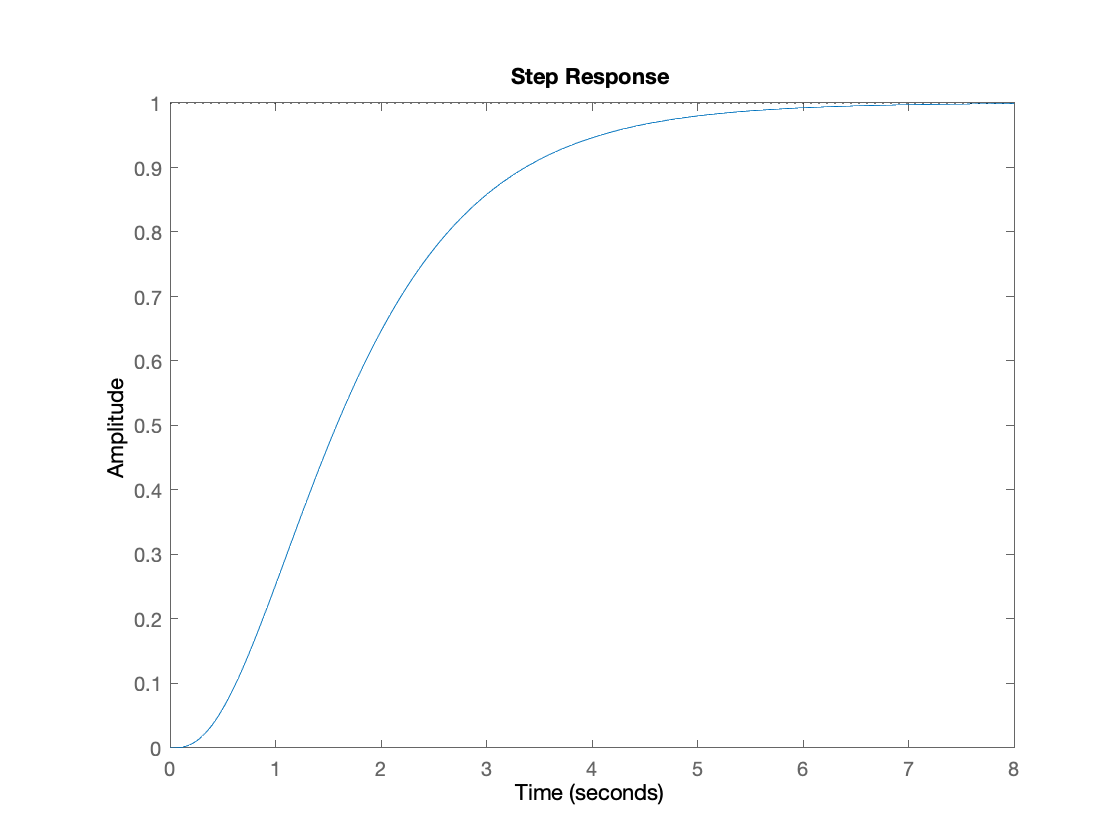

step(GH)  

 From this figure, we determine that settling time:

Ts = 4.95; 

so

T = Ts/4; 

The tangent seems to cross the time axis at 

cmin = 0; tmin = 0.42; 

and the final value at

cmax=1; tmax = 2.674;

Let us add this information to the step response:

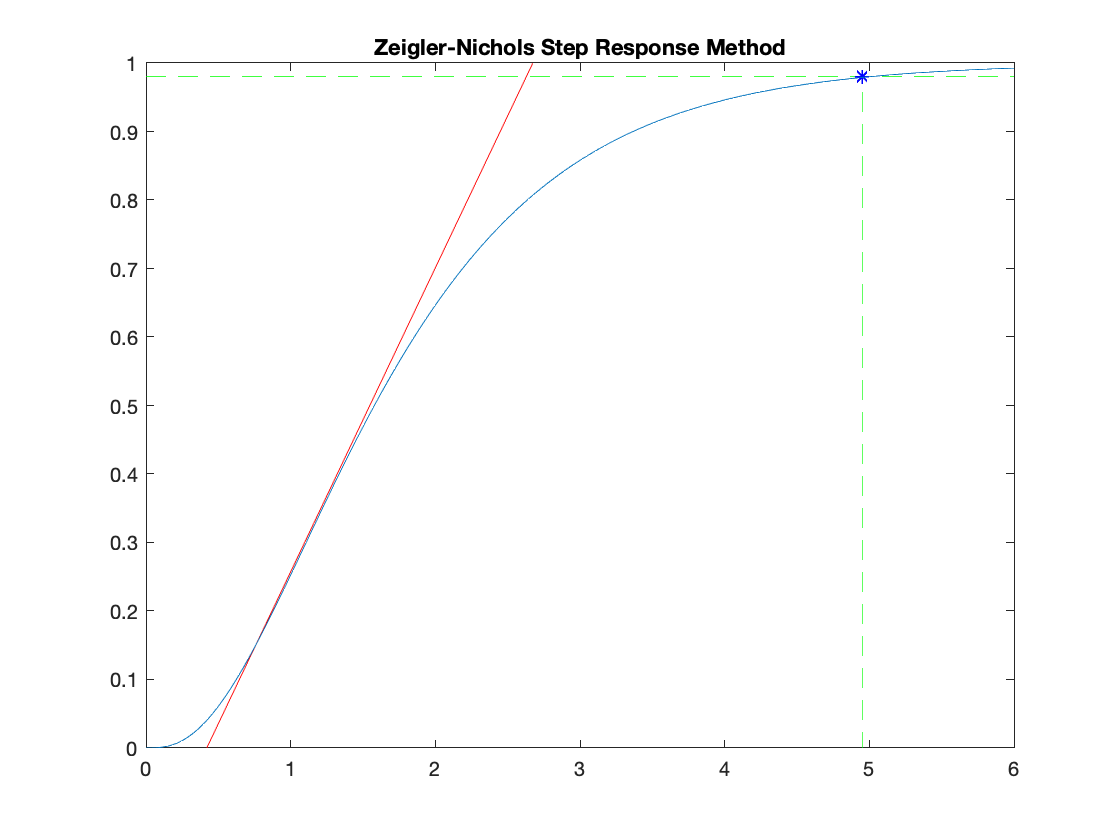

[c,t]=step(GH,6);
plot([tmin,tmax],[cmin,cmax],'r-'),axis([0,6,0,1]),hold on,...
plot([0,6],[0.98,0.98],'g--',[Ts,Ts],[0,0.98],'g--',Ts,0.98,'b*'),...
title('Zeigler-Nichols Step Response Method'),plot(t,c),hold off  

The slope of the tangent is

R = (cmax-cmin)/(tmax-tmin)  

R = 0.4437

The parameter

L = tmin;
L/T 

ans = 0.3394

is in the rquired range so

a=R*L;   

and the PID parameters are

Kprop = 1.2/a; Ti = 2*L; Td = 0.5*L;  

we construct the PID compensator

Prop = tf(1,1);
Integ = tf(1,[Ti,0]);
Deriv = tf([Td,0],1);
PID1 = Kprop*(Prop + Integ + Deriv)  


PID1 =
 
  1.136 s^2 + 5.41 s + 6.44
  -------------------------
           0.84 s
 
Continuous-time transfer function.



PID1z = zpk(PID1) 


PID1z =
 
  1.3524 (s+2.381)^2
  ------------------
          s
 
Continuous-time zero/pole/gain model.



Let us examine the root-locus. The closed-loop poles are:

Gc1 = feedback(PID1*G,H);
[poles,zeros,gain]=zpkdata(Gc1,'v');  

So the root-locus (with closed-loop poles superimposed)

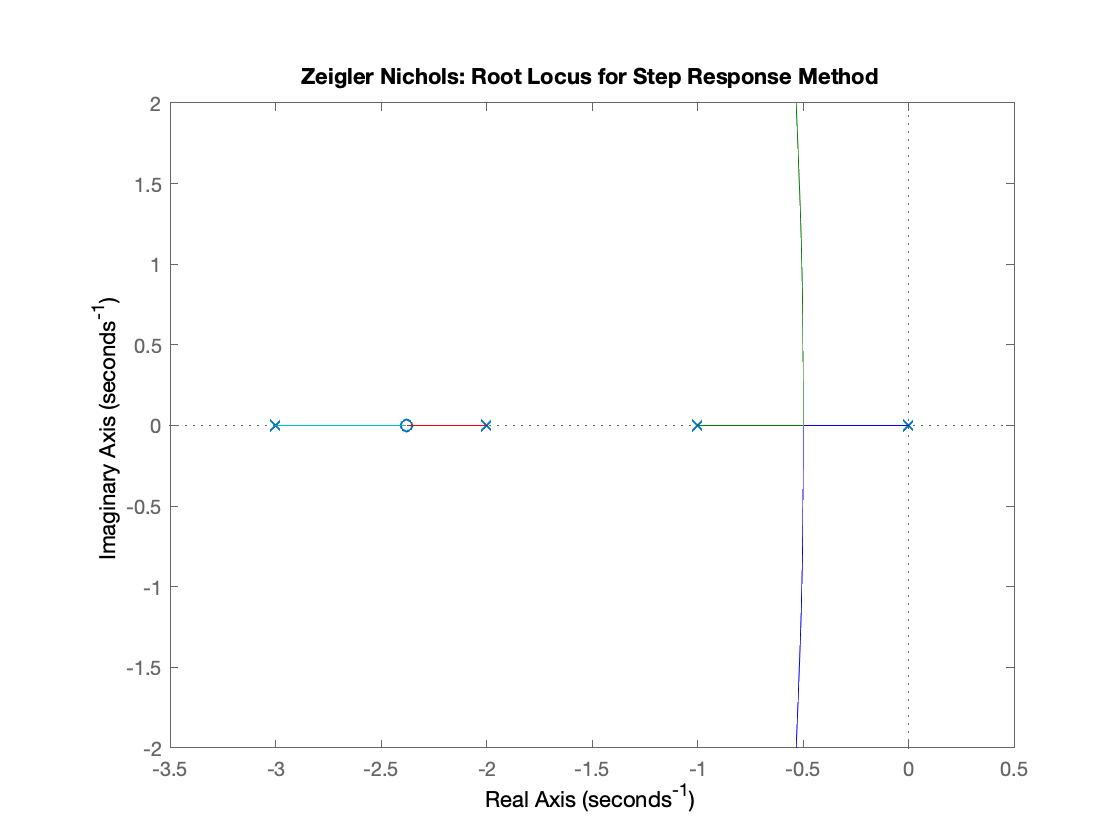

rlocus(PID1*GH),hold on,plot(poles,'*'),...
    title('Zeigler Nichols: Root Locus for Step Response Method'),hold off  

and the step response

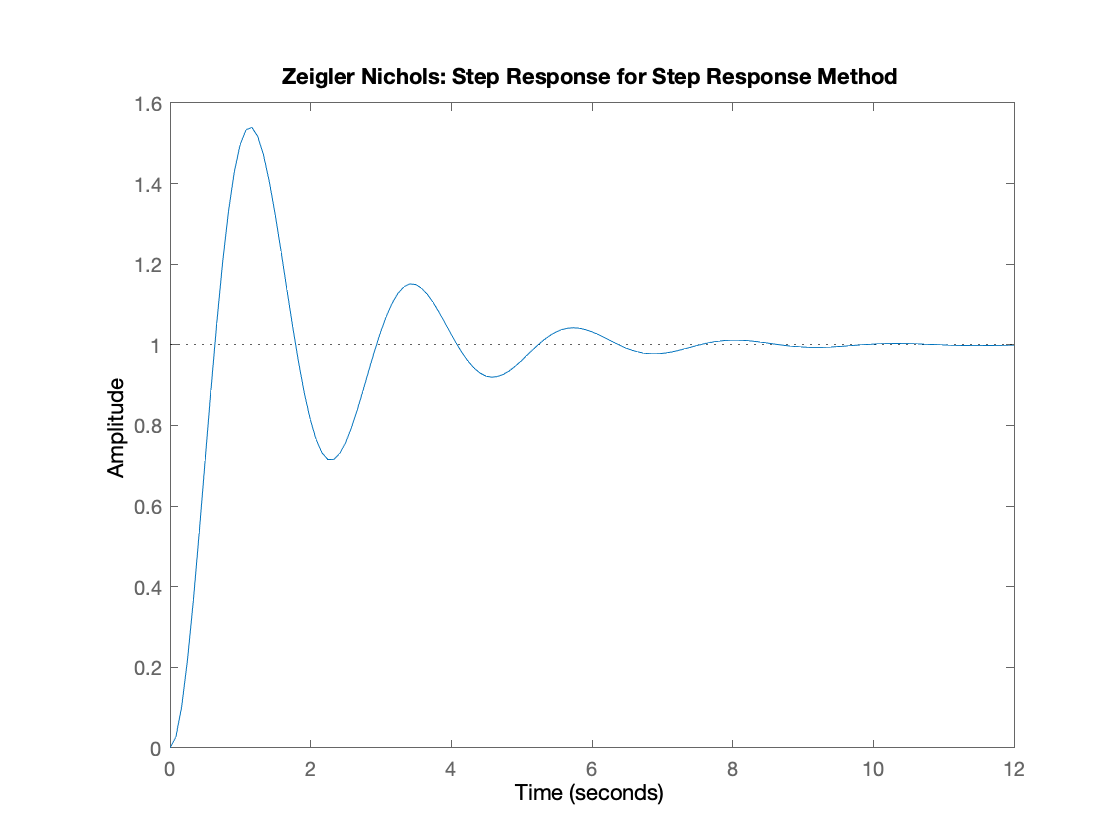

step(Gc1),title('Zeigler Nichols: Step Response for Step Response Method')  

## Ultimate sensitivity method

The open-loop transfer response of the system is $KG(s)H(s)$. We use the Routh-Hurwitz criterion for determine the "ultimate" gain *Ku*.

The closed-loop transfer function is:

                $G_c(s)=\frac{6K}{s^3+6s^2+11s+6(1+K)}.$     .                            (9)

So the closed-loop characteristic equation is:

                  $s^3+6s^2+11s+6(1+K)=0.$       .                              (10)

The routh array is

                   
$$\begin{array}{*{20}{c}}
  {{\text{Order}}}&| & {}&{} \\ 
\hline
  {{s^3}}&| & 1&{11} \\ 
  {{s^2}}&| & 6&{6(1 + K)} \\ 
  {{s^1}}&| & {10 - K}&{} \\ 
  {{s^0}}&| & {6(1 + K)}&{} 
\end{array}$$


So the ultimate gain  $K_u=10$.  

When $K = K_u$ the $s_1$ row is zero and the previous row represents a factor of the characteristic equation. Hence

                     
$$ 6{s^2} + 6(1 + K) = 0 \\ 
  6{s^2} + 66 = 0 \\ 
  {s^2} =  - 11 \\ 
  s =  \pm j\sqrt {11}$$
                             

The ultimate frequency and ultimate period:

                     
$$\omega_u=\sqrt{11}$$
                                       

Ku = 10; Tu = 2*pi/sqrt(11);  

To check the validity of this design:

Kp = dcgain(GH)

Kp = 1

Kp*Ku  

ans = 10

... which is in the suggested range.

The PID parameters are

Kprop = 0.6*Ku; Ti = Tu/2; Td = Tu/8;  

We again construct the PID compensator

Prop = tf(1,1);
Integ = tf(1,[Ti,0]);
Deriv = tf([Td,0],1);
PID2 = Kprop*(Prop + Integ + Deriv)  


PID2 =
 
  1.346 s^2 + 5.683 s + 6
  -----------------------
         0.9472 s
 
Continuous-time transfer function.



PID2z = zpk(PID2)  


PID2z =
 
  1.4208 (s+2.111)^2
  ------------------
          s
 
Continuous-time zero/pole/gain model.



Let us examine the root-locus. The closed-loop poles are:

Gc2 = feedback(PID2*G,H);
[poles,zeros,gain]=zpkdata(Gc2,'v');  

So the root-locus (with closed-loop poles superimposed)

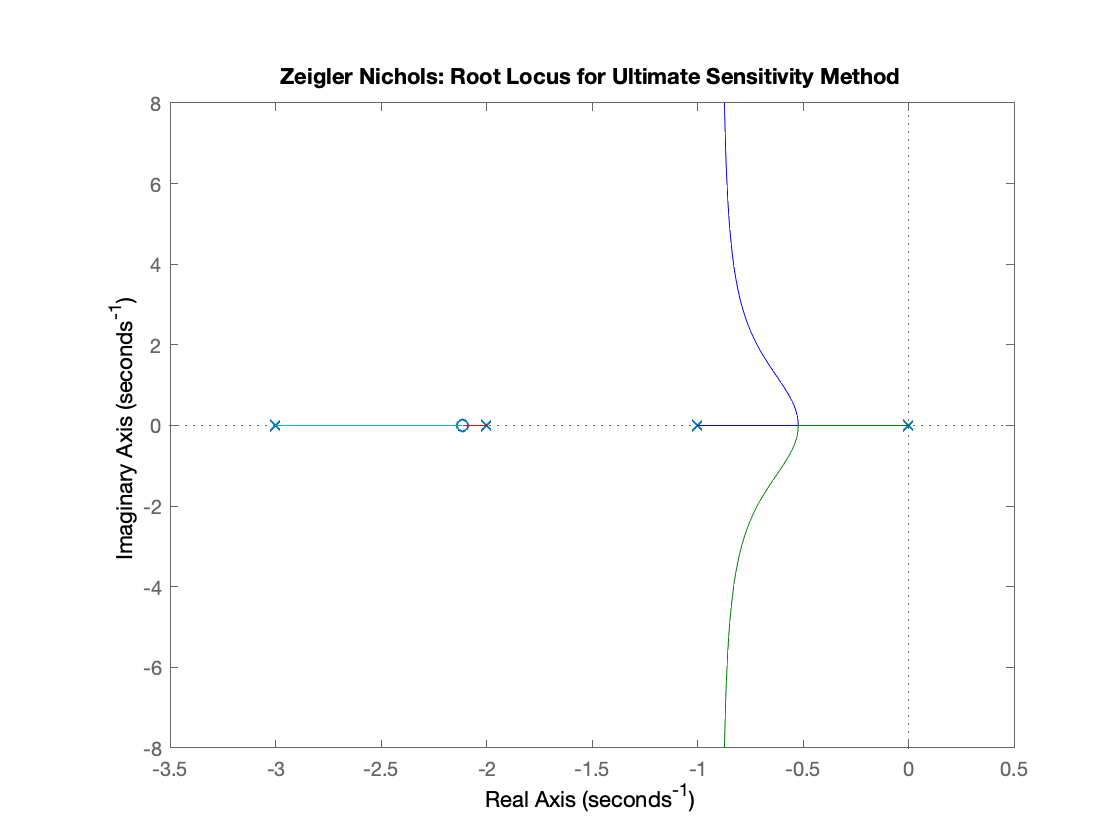

rlocus(PID2*GH),hold on,...
    plot(poles,'*'),...
    title('Zeigler Nichols: Root Locus for Ultimate Sensitivity Method'),hold off  

and the step response

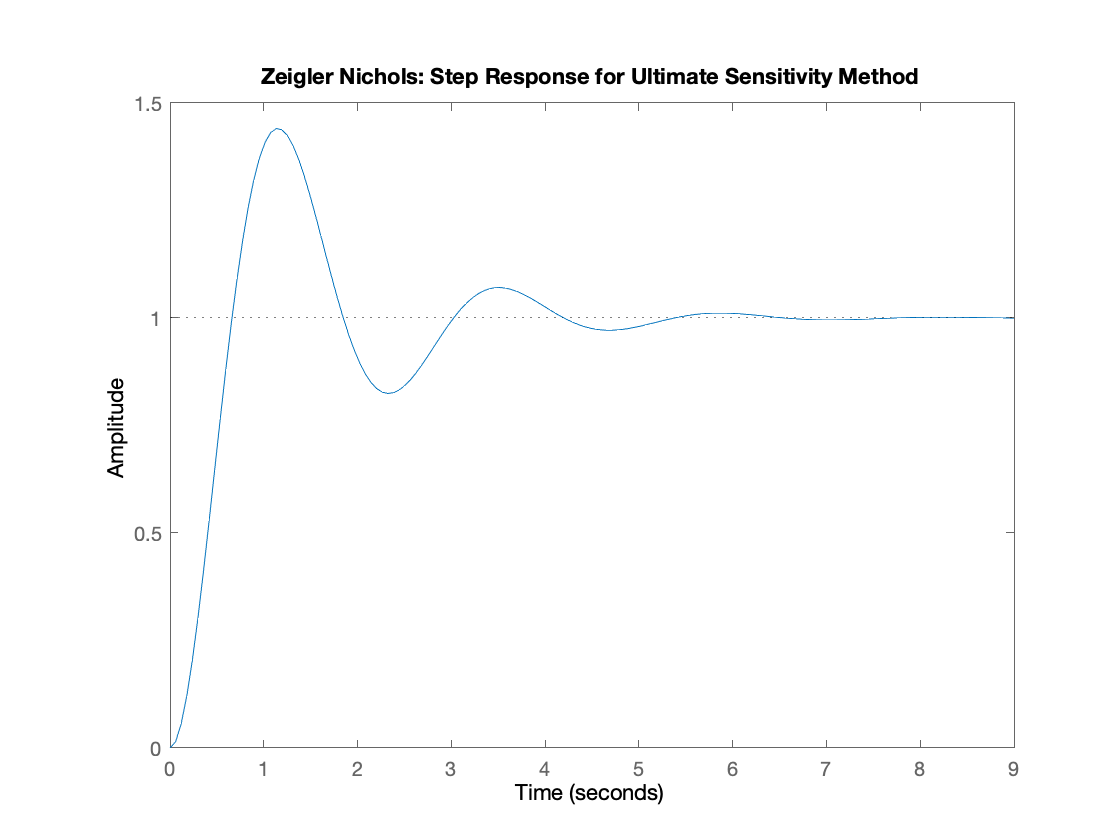

step(Gc2),title('Zeigler Nichols: Step Response for Ultimate Sensitivity Method')  

## Discussion

Comparison of the two designs:

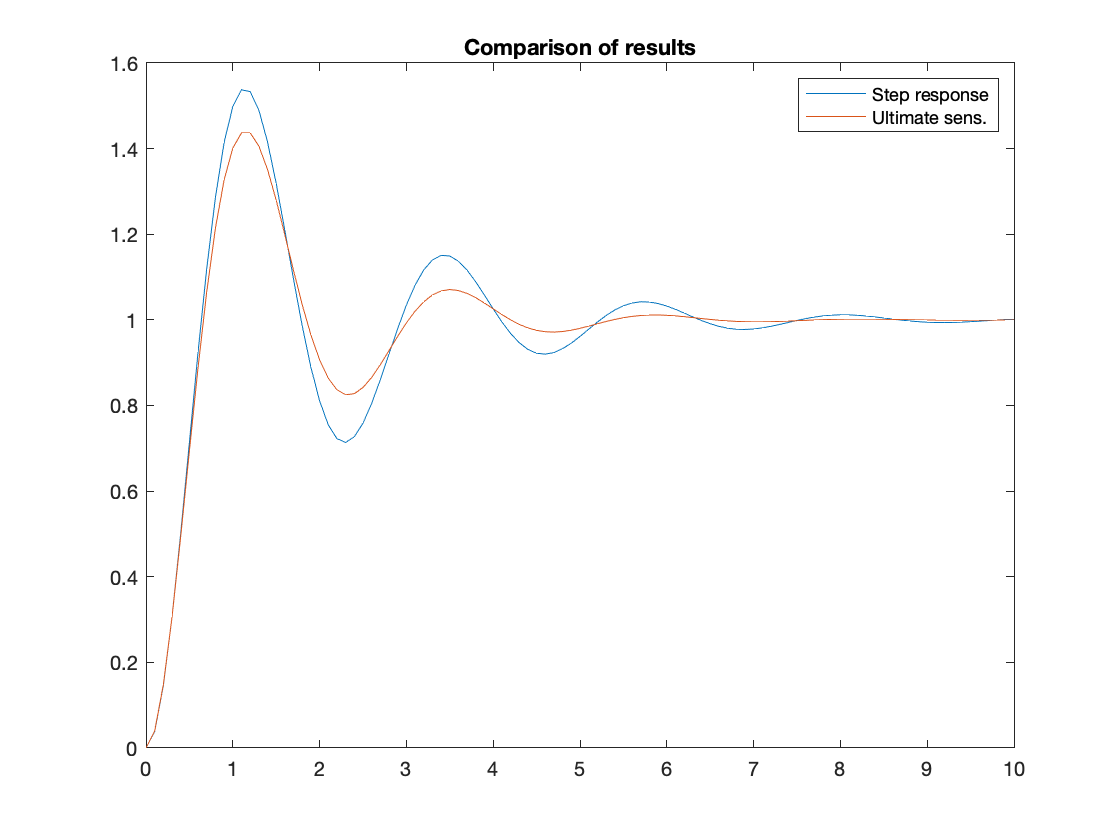

[y1,t1]=step(Gc1,10);
[y2,t2]=step(Gc2,10);
plot(t1,y1,t2,y2),legend('Step response','Ultimate sens.'),...
    title('Comparison of results')  

There is actually very little difference in these two responses. We might choose the result of the ultimate sensitivity as it has a slightly lower peak overshoot. However, it is likely that we can do much better by taking these results as a staring point. 

## Footnotes

[[1]](#_ftnref1) Integral action is hardly ever added to systems of type 1 or greater. The additional pole at the origin is usually extremely destabilising.

[[2]](#_ftnref2) An auto-tuner is a PID compensator that can choose its own parameters. It is naturally a digital device and consists of a microcontroller with some built-in tuning algorithms. Such devices are available commercially.